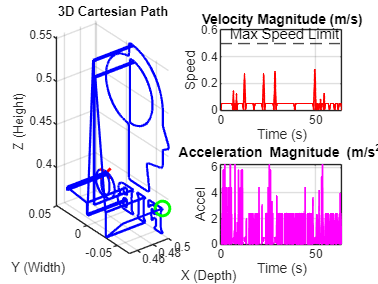

% 1. Load Data
filename = 'FIBO_logo_3D.csv'; % ชื่อไฟล์ CSV ที่ได้จาก Python
data = readtable(filename);

% ดึงข้อมูลแยกตัวแปร
t = data.t;
x = data.x; y = data.y; z = data.z;
vx = data.vx; vy = data.vy; vz = data.vz;
ax = data.ax; ay = data.ay; az = data.az;

% คำนวณความเร็วรวม (Velocity Magnitude)
v_mag = sqrt(vx.^2 + vy.^2 + vz.^2);
a_mag = sqrt(ax.^2 + ay.^2 + az.^2);

% --- PLOT 1: 3D Path Visualization ---
figure('Name', 'UR5 Trajectory Check', 'Color', 'w');
subplot(2, 2, [1 3]); % Plot ใหญ่ซ้ายมือ
plot3(x, y, z, 'b-', 'LineWidth', 1.5); hold on;
plot3(x(1), y(1), z(1), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Start
plot3(x(end), y(end), z(end), 'rx', 'MarkerSize', 10, 'LineWidth', 2); % End
grid on; axis equal;
xlabel('X (Depth)'); ylabel('Y (Width)'); zlabel('Z (Height)');
title('3D Cartesian Path');
view(3); % มุมมอง 3D

% --- PLOT 2: Velocity Profile ---
subplot(2, 2, 2);
plot(t, v_mag, 'r-', 'LineWidth', 1.2);
grid on;
title('Velocity Magnitude (m/s)');
xlabel('Time (s)'); ylabel('Speed');
yline(0.5, '--k', 'Max Speed Limit'); % สมมติ Limit ที่ 0.5 m/s

% --- PLOT 3: Acceleration Profile ---
subplot(2, 2, 4);
plot(t, a_mag, 'm-', 'LineWidth', 1.2);
grid on;
title('Acceleration Magnitude (m/s^2)');
xlabel('Time (s)'); ylabel('Accel');


fprintf('ตรวจสอบข้อมูลพื้นฐาน:\n');

ตรวจสอบข้อมูลพื้นฐาน:


fprintf('เวลาทั้งหมด: %.2f วินาที\n', t(end));

เวลาทั้งหมด: 63.66 วินาที


fprintf('ความเร็วสูงสุดที่พบ: %.4f m/s\n', max(v_mag));

ความเร็วสูงสุดที่พบ: 0.3000 m/s


fprintf('ความเร่งสูงสุดที่พบ: %.4f m/s^2\n', max(a_mag));

ความเร่งสูงสุดที่พบ: 6.2500 m/s^2
